We start by selecting a parcellation of an atlas

parcellation = siibra.getParcellation("human", "julich 2.9");

    "Resolved query 'human' to: Multilevel Human Atlas"

    "Resolved query 'julich 2.9' to: Julich-Brain Cytoarchitectonic Atlas (v2.9)"



The region hierarchy is a tree structure which is represented as a directed graph.

parcellation.RegionTree

ans =   digraph with properties:

    Edges: [582×2 table]
    Nodes: [582×3 table]


Each Node in the graph is a region

parcellation.RegionTree.Nodes

ans = 582×3 table
                                                    Name                                                                          RegionName                                 Region         
    _____________________________________________________________________________________________________    ____________________________________________________    _______________________

    {'https://openminds.ebrains.eu/instances/parcellationEntityVersion/004c917c0eb4c870ce63041f4d76fa07'}    "Area hIP8 (IPS) left"                                  1×1 siibra.items.Region
    {'https://openminds.ebrains.eu/instances/parcellationEntityVersion/008003dbe2bad00cbe6e1230c76b581c'}    "Area 1 (PostCG)"                                       1×1 siibra.items.Region
    {'https://openminds.ebrains.eu/instances/parcellationEntityVersion/013f101693e1bf1f77daad82a6a474f4'}    "Area hOc4d (C

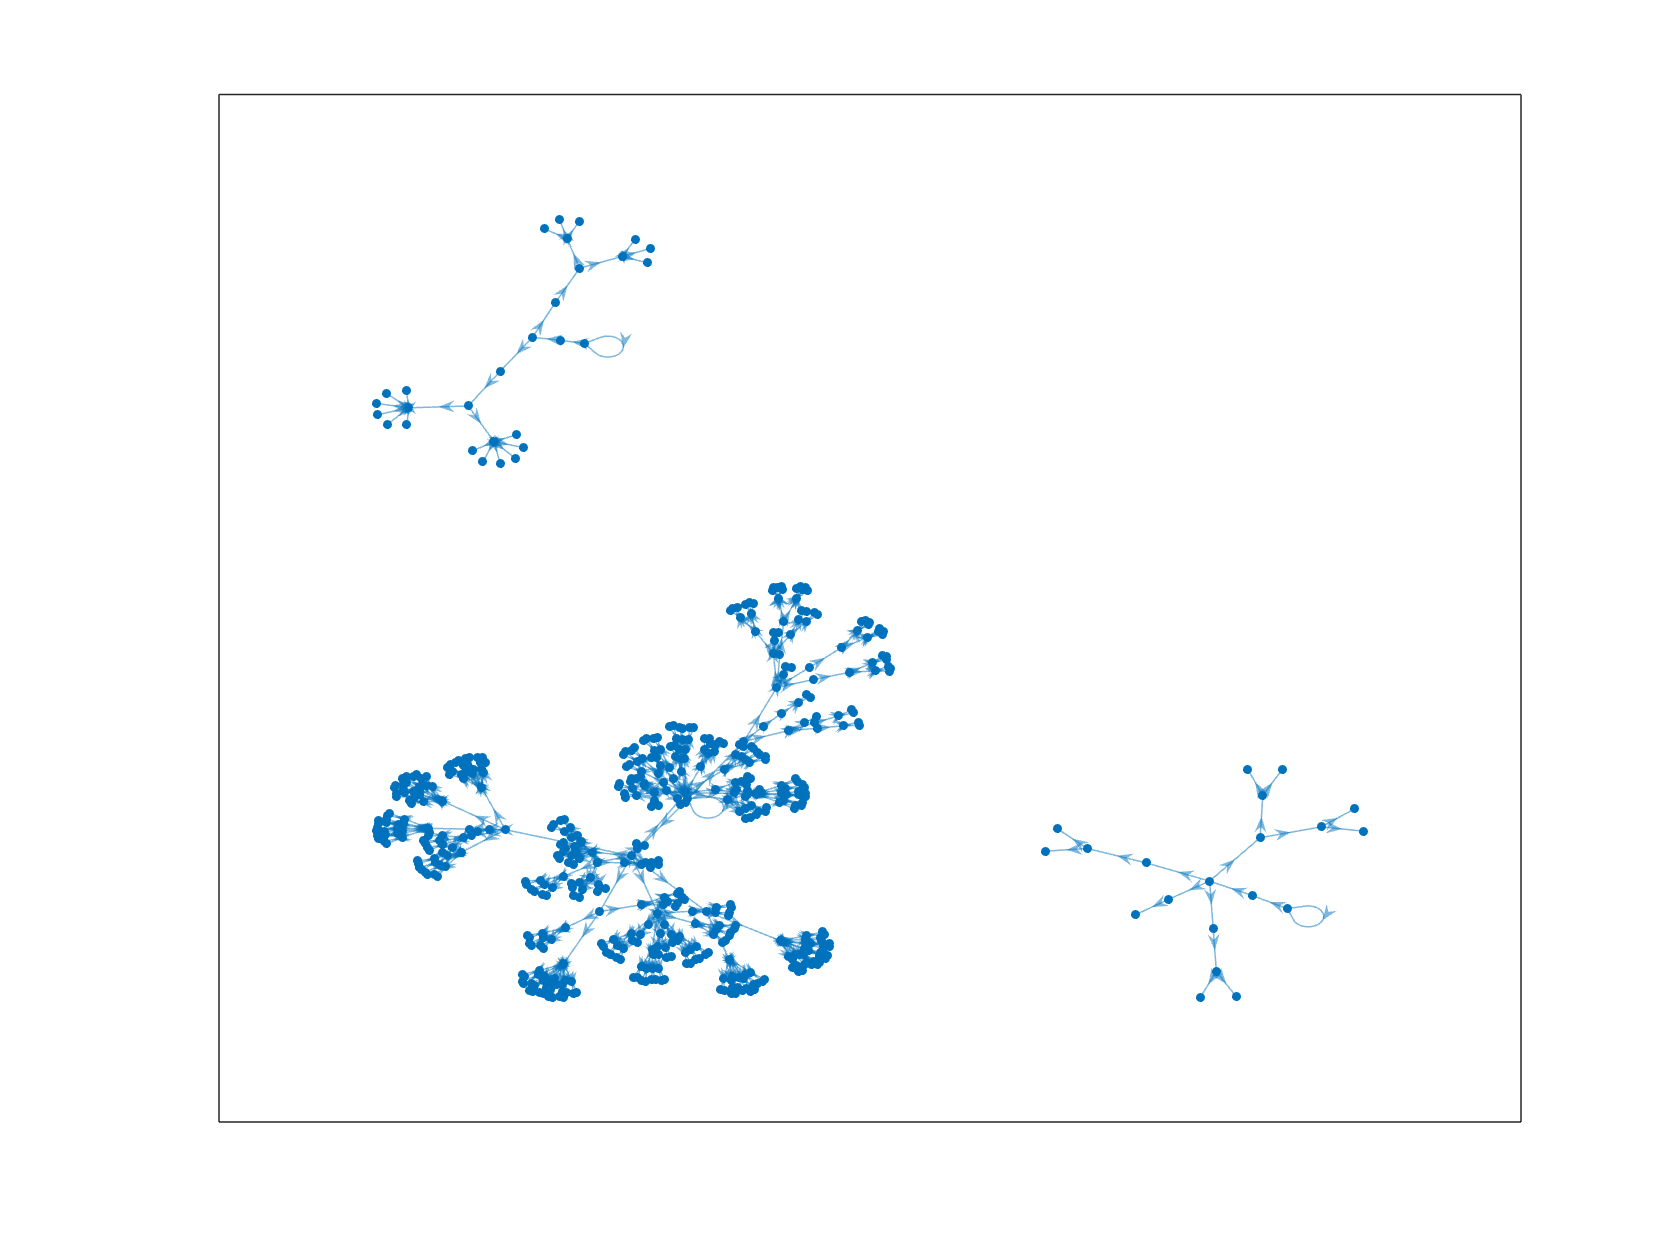

plot(parcellation.RegionTree, 'Layout','force')

% To iterate the leaf regions
regions = parcellation.RegionTree.Nodes.Region;
leafRegions = regions(arrayfun(@(region) region.isLeaf(), regions));
arrayfun(@(r) display(r.Name), leafRegions(1:2), 'UniformOutput', false)

    "Area hIP8 (IPS) left"

    "Area hOc4d (Cuneus) left"

